# Paper number 1: Jacobianless

# Paper number 1 live script

## Jabcobianless adaptive tracking control of manipulators directly on cartesian space

Peter I. Chang, A.-C. Huang, and M.-H. Wu

## Jabcobianless adaptive tracking control of manipulators directly on cartesian space

Peter I. Chang, A.-C. Huang, and M.-H. Wu

### Abstract

The paper contribution. Using a direct work space adaptive controller law, applied directly to the Dynamics Equation of a plannar r-r manipulator, with known/unkown parameters, for all m1, m2, I1, I2 and lc1, lc2 with unknown variation and have the adaptive controller adapt to it, such we use only the tracking error from the work space to run the controller with feedback. This is developed from the standard adaptive law (with tracking error with known case from Craig), then using Slotine-Li standard way (compiled with Spong's tutorial), then modified with the two FAT i/ii paper from Huang, thus finally using this newest direct adaption, with cases for sudden inertia and moment change and so on....

### Intro

The usual paper reviews.

### Methods

The paper is great because it has no jabobian used. Assuming a n-link robot manipulator with fixed rigid length, standard dynamic eqation is:

$D(q)\ddot{q}+C(q,\dot{q})+g(q) = \tau$. (2.1)

Where $q \in R^n$ is the generalized co-ordiante, used as the joint space. $D(q) \in R^{n \times n}$ is the inertia matrix, composed of both the translational and rotational inertia ($M, J
 $), $C(q,\ddot{q}) \in R^{n \times n}$ is the Coriolis force term, along with its centripetal force matrix, working on the joint space, and $g(q) \in R^n $ is the gravity vector, showing all gravity pull on the joints. Finally, the $\tau \in R^n$ is the joint moment, as usually provided from the motor at the joint space, and in our control application, this is to design and control a intented $\tau$, such that all the joint space output $q$, can be tracked with the desired trajectory $q_d \in R^n$, and at the same time, keeping all internal states, such that all $(\dot{q}, \ddot{q})$ are bounded.

#### Torque calculation (Craig's method)

The first method to globally use a non-linear structure for controlling such highly nonlinear method is by Craig's method. Namely torque compenstion in advance.

Modifying eqation (2.1) by making it track an error of $e_d = q_d-q$, this Craig let torqe ($\tau$)  controller as:

$\tau = C\ddot{q} + g + D[\ddot{q}_d +K_v (\dot{q}_d-\dot{q})+K_p(q_d-q)]$ (2.2)

and by replacing it back into (2.1), one has a simple

$\ddot{e}_q + K_v \dot{e}_q + K_p e_q = 0$ (2.3)

(Though this seems trivial, this is not ideal ) Here $(K_v, K_p)$ are (velocity) gains, and (position) gains respectively, yet to be determined.

The basic idea here is that give know $(D, C, g)$ parameters, albit they are essentially if 2 by 2 linkage x-y arm...

$\left[\matrix{D_{11}(t) & D_{12}(t) \cr D_{21}(t) & D_{22}(t)}\right]$, $\left[\matrix{C_{11}(t) & C_{12}(t) \cr C_{21}(t) & C_{22}(t)}\right]$, $\left[\matrix{g_{1}(q_1,q_2)  \cr g_2(q_1,q_2) }\right]$

The paper is great because it has no jabobian used. Assuming a n-link robot manipulator with fixed rigid length, standard dynamic eqation is:

$D(q)\ddot{q}+C(q,\dot{q})+g(q) = \tau$. (2.1)

Where $q \in R^n$ is the generalized co-ordiante, used as the joint space. $D(q) \in R^{n \times n}$ is the inertia matrix, composed of both the translational and rotational inertia ($M, J
 $), $C(q,\ddot{q}) \in R^{n \times n}$ is the Coriolis force term, along with its centripetal force matrix, working on the joint space, and $g(q) \in R^n $ is the gravity vector, showing all gravity pull on the joints. Finally, the $\tau \in R^n$ is the joint moment, as usually provided from the motor at the joint space, and in our control application, this is to design and control a intented $\tau$, such that all the joint space output $q$, can be tracked with the desired trajectory $q_d \in R^n$, and at the same time, keeping all internal states, such that all $(\dot{q}, \ddot{q})$ are bounded.

#### Torque calculation Craig's method

The first method to globally use a non-linear structure for controlling such highly nonlinear method is by Craig's method. Namely torque compenstion in advance.

Modifying eqation (2.1) by making it track an error of $e_d = q_d-q$, Craig let torqe ($\tau$)  controller as:

$\tau = C\ddot{q} + g + D[\ddot{q}_d +K_v (\dot{q}_d-\dot{q})+K_p(q_d-q)]$ (2.2)and by replacing it back into (2.1), one has a simple

$\ddot{e}_q + K_v \dot{e}_q + K_p e_q = 0$ (2.3)

% checked c\dot{q}, not c\ddot{q}

Since it is very highlly none liner, and so that one want's to find the full controller design. using eigen structure.... for example:

Though this seems trivial, this is not ideal ) Here $(K_v, K_p)$ are (velocity) gains, and (position) gains respectively, yet to be determined.

The basic idea here is that give know $(D, C, g)$ parameters, albit they are essentially if 2 by 2 linkage x-y arm...

$\left[\matrix{D_{11}(t) & D_{12}(t) \cr D_{21}(t) & D_{22}(t)}\right]$, $\left[\matrix{C_{11}(t) & C_{12}(t) \cr C_{21}(t) & C_{22}(t)}\right]$, $\left[\matrix{g_{1}(q_1,q_2)  \cr g_2(q_1,q_2) }\right]$

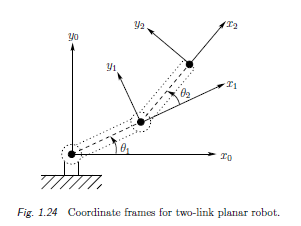

This is a standard 2 link (plannar) x-y co-ordiante system, such that in textbooks, the 


$$\begin{array}{l}
x=x_2 =l_1 \cos \theta_1 +l_2 \cos \left(\theta_1 +\theta_2 \right)\\
y=y_2 =l_1 \sin \theta_1 +l_2 \sin \left(\theta_1 +\theta_2 \right)
\end{array}$$


### Review of Jacobian and its "parametrization difficulty on usage being uncertain and its sinularity"

The Jacobian matrix for such control for only x-y co-ordinate, without "end effector" pose control, with a two by two matrix transformation is:

## Calculation of torque method

since the origianl 